clear; clc; close all;
addpath(genpath(pwd));

%% Root folder path
rootDir = fullfile(project_root(), 'results', 'optimization', 'compare_DTW_ARE_MSE_GZ_v2');

%% Get all subfolders
folderInfo = dir(rootDir);
folderInfo = folderInfo([folderInfo.isdir]);   % Keep folders only
folderInfo = folderInfo(~ismember({folderInfo.name}, {'.', '..'})); % Remove . and ..

%% Struct array for storing results
result = struct( ...
    'folderName', {}, ...
    'avgAoA', {}, ...
    'ampAoA', {}, ...
    'Re', {}, ...
    'f', {}, ...
    'matFilePath', {}, ...
    'A1', {},...
    'b1',{},...
    'A2',{},...
    'b2',{},...
    'Tp',{},...
    'Tf0',{},...
    'Tvl',{},...
    'Tv0',{},...
    'yita',{});

idx = 0;

%% Iterate over all subfolders
for i = 1:length(folderInfo)
    subFolderName = folderInfo(i).name;
    subFolderPath = fullfile(rootDir, subFolderName);

    %-----------------------------
    % Parse folder name
    % Example:-9.4±7_re1e6_0.6
    %-----------------------------
    token = regexp(subFolderName, ...
        '^([+-]?\d+\.?\d*)±([+-]?\d+\.?\d*)_re([0-9eE\+\-\.]+)_([+-]?\d+\.?\d*)$', ...
        'tokens');

    if isempty(token)
        fprintf('Folder name does not match the expected pattern, skipping: %s\n', subFolderName);
        continue;
    end

    token = token{1};

    avgAoA = str2double(token{1});   % mean angle of attack
    ampAoA = str2double(token{2});   % amplitude
    Re     = str2double(token{3});   % Reynolds number
    f      = str2double(token{4});   % frequency

    %-----------------------------
    % Find mat file
    %-----------------------------
    matFileName = 'bl_cfd_final_optimized_parameters_GZ.mat';
    matFilePath = fullfile(subFolderPath, matFileName);

    if ~isfile(matFilePath)
        fprintf('File not found: %s\n', matFilePath);
        continue;
    end

    %-----------------------------
    % Read MAT-file data
    % load returns a struct containing all variables from the MAT file
    %-----------------------------
    load(matFilePath);

    %-----------------------------
    % Save to the result struct
    %-----------------------------
    idx = idx + 1;
    result(idx).folderName = subFolderName;
    result(idx).avgAoA     = avgAoA;
    result(idx).ampAoA     = ampAoA;
    result(idx).Re         = Re;
    result(idx).f          = f;
    result(idx).matFilePath = matFilePath;
    result(idx).A1      = para_local(1);
    result(idx).b1      = para_local(2);
    result(idx).A2      = para_local(3);
    result(idx).b2      = para_local(4);
    result(idx).Tp      = para_local(5);
    result(idx).Tf0      = para_local(6);
    result(idx).Tvl      = para_local(7);
    result(idx).Tv0      = para_local(8);
    result(idx).yita      = para_local(9);

end

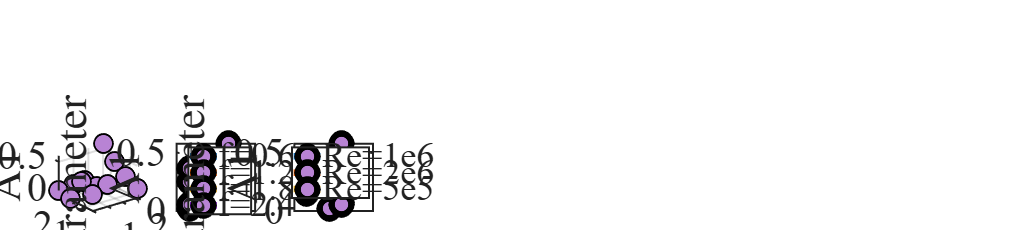

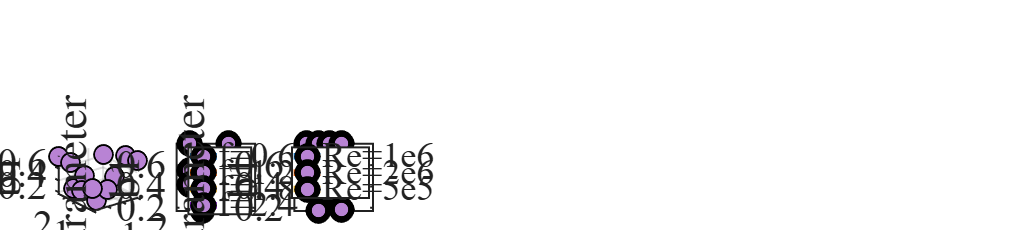

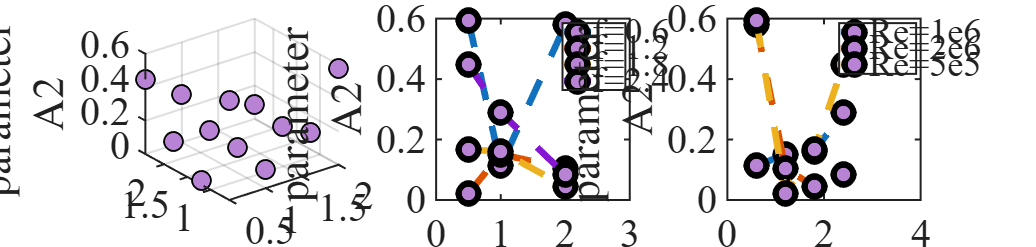

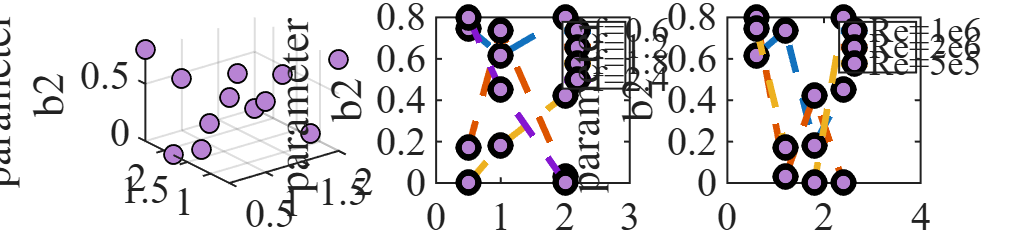

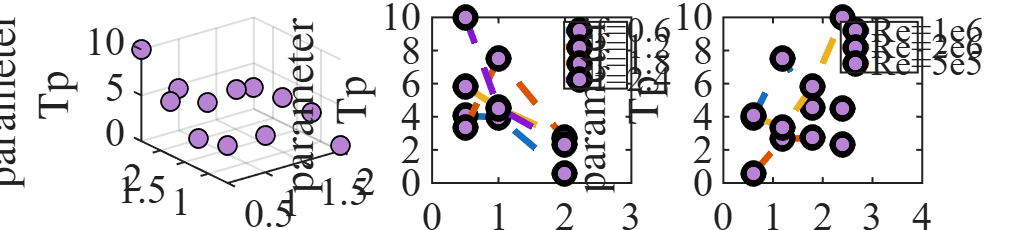

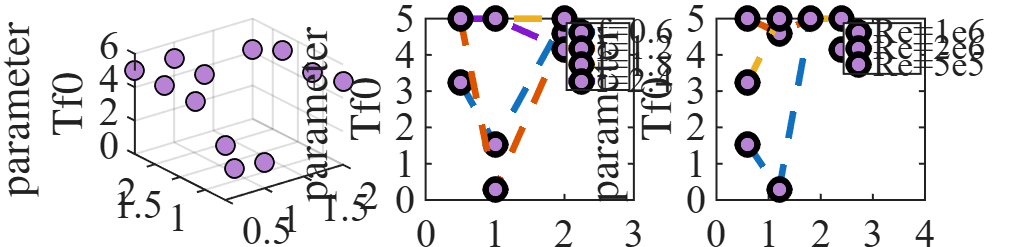

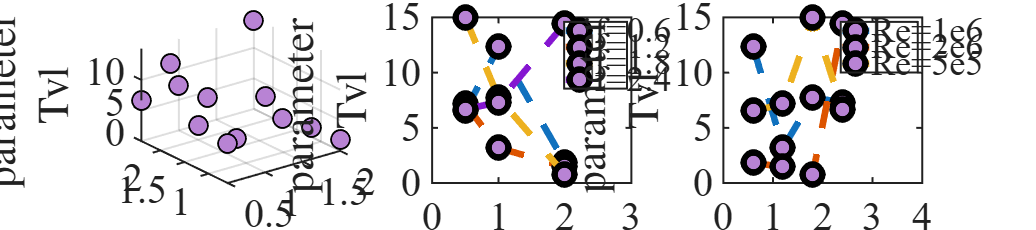

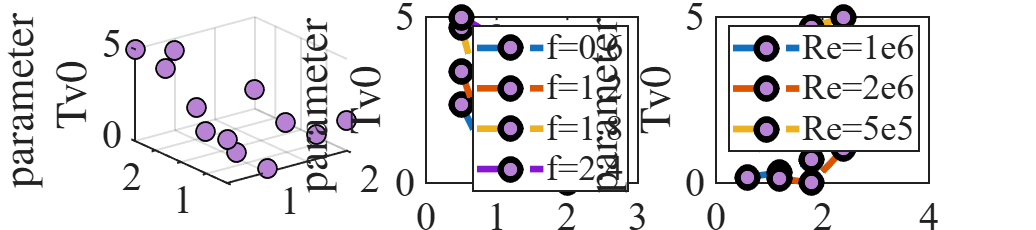

structname =  fieldnames(result);
param = structname(7:15);

for j = 1 : length(param)
    x = [];
    y = [];
    z = [];
    for i = 1: length(result)
        if result(i).avgAoA == -9.4
            firstname = num2str(result(i).avgAoA);
            x = [x result(i).Re/1e6];
            y = [y result(i).f];
            z = [z result(i).(param{j})];
        end
    end
    filename = [firstname '_' param{j}];
    draw_scatter(x,y,z,filename)
end



function draw_scatter(x,y,z,filename)
    target = split(filename,'_');
    target = target(2);

    if strcmp(target, 'yita')
        target = '$\eta$';
    end

    fontsize = 30;
    markersize = 200;
    markesize = 15;
    lgdwidth = 50;
    color = [184/255 131/255 212/255];
    fig1 = figure('Color','w','Position',[100 100 3600 800]);

    subplot(1,3,1)
    scatter3(x,y,z,markersize,LineWidth=1.5,MarkerEdgeColor='k',MarkerFaceColor=color)
    xlabel('Re/$\times 10^6$',...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    ylabel('f/Hz',...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    zlabel(['parameter ' target],...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    set(gca,'FontName','Times New Roman','Fontsize',fontsize,'LineWidth',1.5);

    subplot(1,3,2)
    for i = 1 : 4
        plot([x(i+8),x(i),x(i+4)],[z(i+8),z(i),z(i+4)],'--', 'LineWidth', 5,'Markersize',markesize,'Marker','o','MarkerEdgeColor','k','MarkerFaceColor',color) ;
        hold on
    end
    lgd = legend('f=0.6','f=1.2','f=1.8','f=2.4');
    lgd.IconColumnWidth = lgdwidth;
    xlabel('Re/$\times 10^6$',...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    ylabel(['parameter ' target],...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    xlim([0 3])
    set(gca,'FontName','Times New Roman','Fontsize',fontsize,'LineWidth',1.5);

    subplot(1,3,3)
    for i = [1 5 9]
        plot([y(i),y(i+1),y(i+2),y(i+3)],[z(i),z(i+1),z(i+2),z(i+3)],'--', 'LineWidth', 5,'Markersize',markesize,'Marker','o','MarkerEdgeColor','k','MarkerFaceColor',color) ;
        hold on
    end
    lgd = legend('Re=1e6','Re=2e6','Re=5e5');
    lgd.IconColumnWidth = lgdwidth;
    xlabel('f/Hz',...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    ylabel(['parameter ' target],...
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize)
    xlim([0 4])
    set(gca,'FontName','Times New Roman','Fontsize',fontsize,'LineWidth',1.5);
    name = [filename '.pdf'];
    exportgraphics(fig1,name,'ContentType', 'vector')
end